# 时域实验🧪

## 一、系统辨识建模

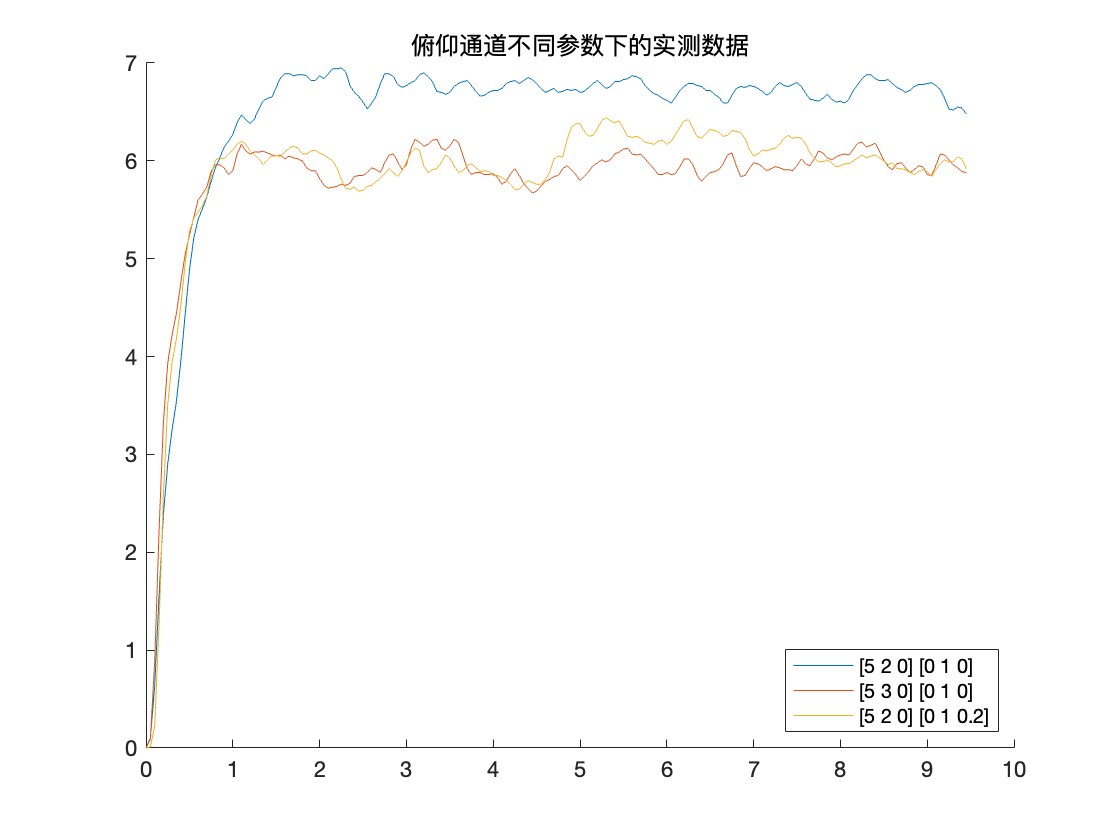

%读取实验所测得数据这里使用pitch数据
sheets=sheetnames("TimeDomain.xlsx");
data=readmatrix("TimeDomain.xlsx","Sheet",sheets(1));
cont=readmatrix("TimeDomain.xlsx","Sheet","pitchparam");
figure();hold on;
for i=1:3
    label=sprintf("[%s] [%s]",join(string(cont(i,1:3))),join(string(cont(i,4:6))));
    plot(data(:,2*i-1),data(:,2*i),'DisplayName',label)
end
title("俯仰通道不同参数下的实测数据")
legend('Location',"southeast")

进行系统辨识

t=data(:,1);
y=data(:,2);
nt=4;
N=length(y)-nt;
u=[zeros(nt,1);ones(N,1)];
data=iddata(y,u,1);

'iddata' 需要 System Identification Toolbox。

idsys=tfest(data2,3,0);